Setting up symbolic equations

syms F Fx Fy alpha theta mass g inertia cm test dL 'real'

syms x y dx dy ddx ddy th dth ddth blaFx blaFy 'real'

%creating generalized coords
q = [x; y; th];
dq = [dx; dy; dth];
ddq = [ddx; ddy; ddth];

Position and velocity:

% position and velocity
posRocket = [x;y];

velocRocket = jacobian(posRocket, q) * dq;

Potential and Kinetic Energy:

% kinetic
KineticEnergyRocket = 0.5*mass*transpose(velocRocket)*velocRocket+ 0.5*inertia*(dth)^2; %0.5mv^2
KineticEnergyRocket = simplify(KineticEnergyRocket)

$$KineticEnergyRocket = \frac{\mathrm{inertia}\,{\mathrm{dth}}^{2}}{2}+\frac{\mathrm{mass}\,{\mathrm{dx}}^{2}}{2}+\frac{\mathrm{mass}\,{\mathrm{dy}}^{2}}{2}$$


% Potential energy
PotentialEnergyRocket = mass*[0 g]*posRocket  %MGH ([0 g] means only y is used - height)

$$PotentialEnergyRocket = g\,\mathrm{mass}\,y$$

Manipulator terms?

M = simplify(hessian(KineticEnergyRocket, dq))

$$M = \left(\begin{array}{ccc} \mathrm{mass} & 0 & 0\\ 0 & \mathrm{mass} & 0\\ 0 & 0 & \mathrm{inertia} \end{array}\right)$$


dM = sym(zeros(size(M)));
for i = 1:size(dM, 1)
    for j = 1:size(dM, 2)
        dM(i,j) = jacobian(M(i,j), q) * dq;
    end
    
end
dM = simplify(dM)

$$dM = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$


C = dM*dq - transpose(jacobian(KineticEnergyRocket, q));
C = simplify(C)

$$C = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$


G = (jacobian(PotentialEnergyRocket, q)')

$$G = \left(\begin{array}{c} 0\\ g\,\mathrm{mass}\\ 0 \end{array}\right)$$

Input Forces:

% rotation matrix
R = [ cos(th) -sin(th)
      sin(th)  cos(th)];
 
% location of the input forces
fx = [x; y] + R * [ 0;-3.5];
fy = [x; y] + R * [0; -3.5];

% input force with respect to inertia
f1 = R * [-Fx; 0];
f2 = R * [0; Fy];

% partial derivatives
Q1 = simplify(f1' * jacobian(fx, q))';
Q2 = simplify(f2' * jacobian(fy, q))';

%F = 2;
% calculate B matrix
B = jacobian(Q1 + Q2, [Fx; Fy])

$$B = \left(\begin{array}{cc} -\cos\left(\mathrm{th}\right) & -\sin\left(\mathrm{th}\right)\\ -\sin\left(\mathrm{th}\right) & \cos\left(\mathrm{th}\right)\\ -\frac{7}{2} & 0 \end{array}\right)$$

Linearise the model

%blaFx = -F*sin(alpha+th)
%blaFy=F*cos(alpha+th)
u = [Fx;Fy];
%u = [-F*sin(alpha+th);F*cos(alpha+th)];
%Fy = F*sin(alpha+theta)
% the backslash operator \ solves the equation Ax = b
% more efficienctly than x = inv(A) * b
acceleration_eqns = simplify(M \ (-C - G + B*u))

$$acceleration\_eqns = \left(\begin{array}{c} -\frac{\mathrm{Fx}\,\cos\left(\mathrm{th}\right)+\mathrm{Fy}\,\sin\left(\mathrm{th}\right)}{\mathrm{mass}}\\ -\frac{g\,\mathrm{mass}-\mathrm{Fy}\,\cos\left(\mathrm{th}\right)+\mathrm{Fx}\,\sin\left(\mathrm{th}\right)}{\mathrm{mass}}\\ -\frac{7\,\mathrm{Fx}}{2\,\mathrm{inertia}} \end{array}\right)$$

dyn = [acceleration_eqns; dq];

% Jacobian of dynamics, with the operating point subbed in
A = jacobian(dyn, [dq.', q.']);
A = subs(A, [dq.', q.', u.'], [0,0,0,0,0,0,0,mass*g])

$$A = \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & -g\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0 \end{array}\right)$$


B = jacobian(dyn, [u.']);
B = subs(B, [dq.',q.',u.'],[0,0,0,0,0,0,0,mass*g])

$$B = \left(\begin{array}{cc} -\frac{1}{\mathrm{mass}} & 0\\ 0 & \frac{1}{\mathrm{mass}}\\ -\frac{7}{2\,\mathrm{inertia}} & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0 \end{array}\right)$$

Make state space things and sub in values

% Params needed for simulation
m_ = 1000;
w_ = 0;
I_ = 1/12 * m_ *(15^2+5^2)+m_*4^2;%parrale
g_ = 9.81;
a_=0;

% Subsitute to get numerical A and B
A = double(subs(A, [mass,inertia,g], [m_,I_,g_]))

A =          0         0         0         0         0   -9.8100
         0         0         0         0         0         0
         0         0         0         0         0         0
    1.0000         0         0         0         0         0
         0    1.0000         0         0         0         0
         0         0    1.0000         0         0         0


B = double(subs(B, [mass,inertia,g], [m_,I_,g_]))

B = 	1.0e+-3 *

   -1.0000         0
         0    1.0000
   -0.0950         0
         0         0
         0         0
         0         0



C = eye(6);

D = [0;];

states = {'dx' 'dy' 'dth' 'x' 'y' 'th'};
inputs = {'f'};
outputs = {'dx' 'dy' 'dth' 'x' 'y' 'th'};

sys_ss = ss(A, B, C, D, 'statename', states,...
                        'inputname', inputs,...
                        'outputname', outputs)

sys_ss =
 
  A = 
           dx     dy    dth      x      y     th
   dx       0      0      0      0      0  -9.81
   dy       0      0      0      0      0      0
   dth      0      0      0      0      0      0
   x        1      0      0      0      0      0
   y        0      1      0      0      0      0
   th       0      0      1      0      0      0
 
  B = 
              f(1)        f(2)
   dx       -0.001           0
   dy            0       0.001
   dth  -9.502e-05           0
   x             0           0
   y             0           0
   th            0           0
 
  C = 
         dx   dy  dth    x    y   th
   dx     1    0    0    0    0    0
   dy     0    1    0    0    0    0
   dth    0    0    1    0    0    0
   x      0    0    0    1    0    0
   y      0    0    0    0    1    0
   th     0    0    0    0    0    1
 
  D = 
        f(1)  f(2)
   dx      0     0
   dy      0     0
   dth     0     0
   x       0     0
   y       0     0
   th      0     0
 
C

Regulation and control I think

Q = eye(6);
Q(4,4) = 100000;%penalty matricies pos x
Q(5,5) = 100000; %pos y
Q(6,6) = 100; %theta
R = eye(2)

R =      1     0
     0     1



% calculate LQR gain

K = lqr(A, B, Q, R)        

K = 	1.0e+04 *

    0.1279   -0.0000   -3.5012    0.0316    0.0000   -2.5389
    0.0000    0.0795   -0.0000    0.0000    0.0316   -0.0000


Build state spaces

Ac = [(A-B*K)];
Bc = [B];
Cc = [C];
Dc = [D];

sys_cl = ss(Ac, Bc, Cc, Dc, 'statename', states,...
                            'inputname', inputs,...
                            'outputname', outputs);
                        

Test this step response

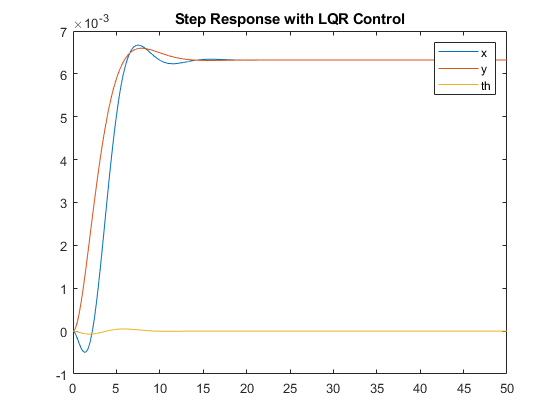

t = 0:0.001:50;
r = 2*ones(length(t), 2);
[y,t,x] = lsim(sys_cl, r, t);

% plot the position states
plot(t, y(:, 4:6));
legend(["x"; "y"; "th"]);
title('Step Response with LQR Control')

Now augmented:

% New integrator states for error on positions x and y
newA = [0, 0, 0, 1, 0, 0, 0, 0;...
        0, 0, 0, 0, 1, 0, 0, 0];
tempA = horzcat(A, zeros(6,2));

% New A Matrix (aug = augmented)
A_aug = vertcat(tempA, newA);

% New B Matrix
B_aug = vertcat(B, zeros(2,2));

% New C matrix
C_aug = eye(8);

% weighting system - Weighting integral states more
% for SS tracking
Q = eye(8);
Q(4,4) = 10;%x
Q(5,5) = 100;%y
Q(6,6) = 100;%th
Q(7,7) = 100000;%dx
Q(8,8) = 100000;%dy

R = eye(2);

% calculate new LQR gain
K_aug = lqr(A_aug, B_aug, Q, R)

K_aug = 	1.0e+04 *

    0.3417   -0.0000   -6.3958    0.1470   -0.0000   -5.2715    0.0316    0.0000
   -0.0000    0.1363    0.0000   -0.0000    0.0928    0.0000   -0.0000    0.0316


Simulate aug states

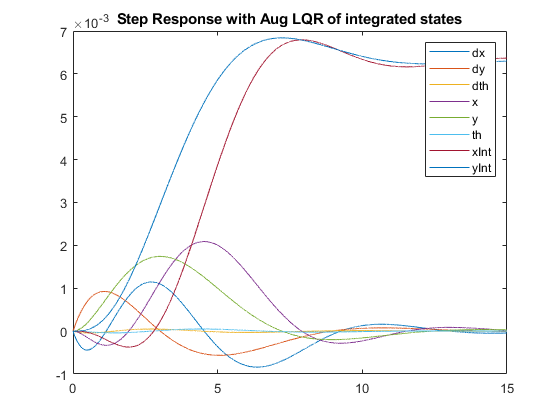

Ac = [(A_aug - B_aug*K_aug)];
Bc = [B_aug];
Cc = [C_aug];
Dc = [D];

states = {'dx' 'dy' 'dth' 'x' 'y' 'th' 'xInt' 'yInt'};
inputs = {'u1' 'u2'};
outputs = {'dx' 'dy' 'dth' 'x' 'y' 'th' 'xInt' 'yInt'};

sys_cl = ss(Ac, Bc, Cc, Dc, 'statename', states,...
                            'inputname', inputs,...
                            'outputname', outputs);

t = 0:0.001:15;
r = 2*ones(length(t), 2);
[y,t,x] = lsim(sys_cl, r, t);
plot(t, y);
legend(states)
title('Step Response with Aug LQR of integrated states')

Sim?

m = m_;
g = g_;
I = I_;
L = w_;

%sim("RandomControllerTestAug")